### **FinalProject_BaseCode.mlx** gives example use of  Arduino Nano33BLE, Sensors, Servos and control structure for Jungle Explorer Rover.

This script creates the code using a set of pre-made functions to control the 3 Rover RC servomotors (steering, drive and pan motor) attached to the three pwm ports on your team's Nano33BLE, to talk to the Rover's UBlox GPS sensor and to read analog sensors from the Nano33BLE analog input pins.

Caution: this robot uses an Arduino Nano 33BLE controller. Please go to the Arduino app, open the **Board Manager **scroll down to **Arduino Mbed OS Nano Boards** and install the correct support software for the Nano 33 BLE.

D Barrett, April-7-22 RevB

**Wiring assumptions **(note: if you change your Rover's wiring you must change code to match !):

It is assumed that the three motors are connected to the Nano33BLE through an Actobotics Servo Power isolation board (as shown below), and that the power isolation board is set up to recieve an RC style **pwm** velocity commands from the Nano33BLE and 5 VDC power from the rovers battery through its speed control unit. 

1) Please plug steering motor into channel 5 and drive motor amplifier into channel 3 as shown. Plug Your pan servos into Channel 6.  

2) Please connect your SparkFun GPS-16329 GPS to the Nuc via USB as shown, be extremly careful with interface cable bewteen SMA and UFL antena cable, you can only plug it into your GPS once or twice. Once plugged in properly, please never remove it. Your GPS is really expensive and this set of hardware is the ONLY ONE, your team gets. No spares.

3) Please add the second Actobotics Servo Power isolation board as shown and then carefully attached all of your Sharp IR and Maxbotix Sonars to them. See Dave B or course assistants for wiring modification details.   

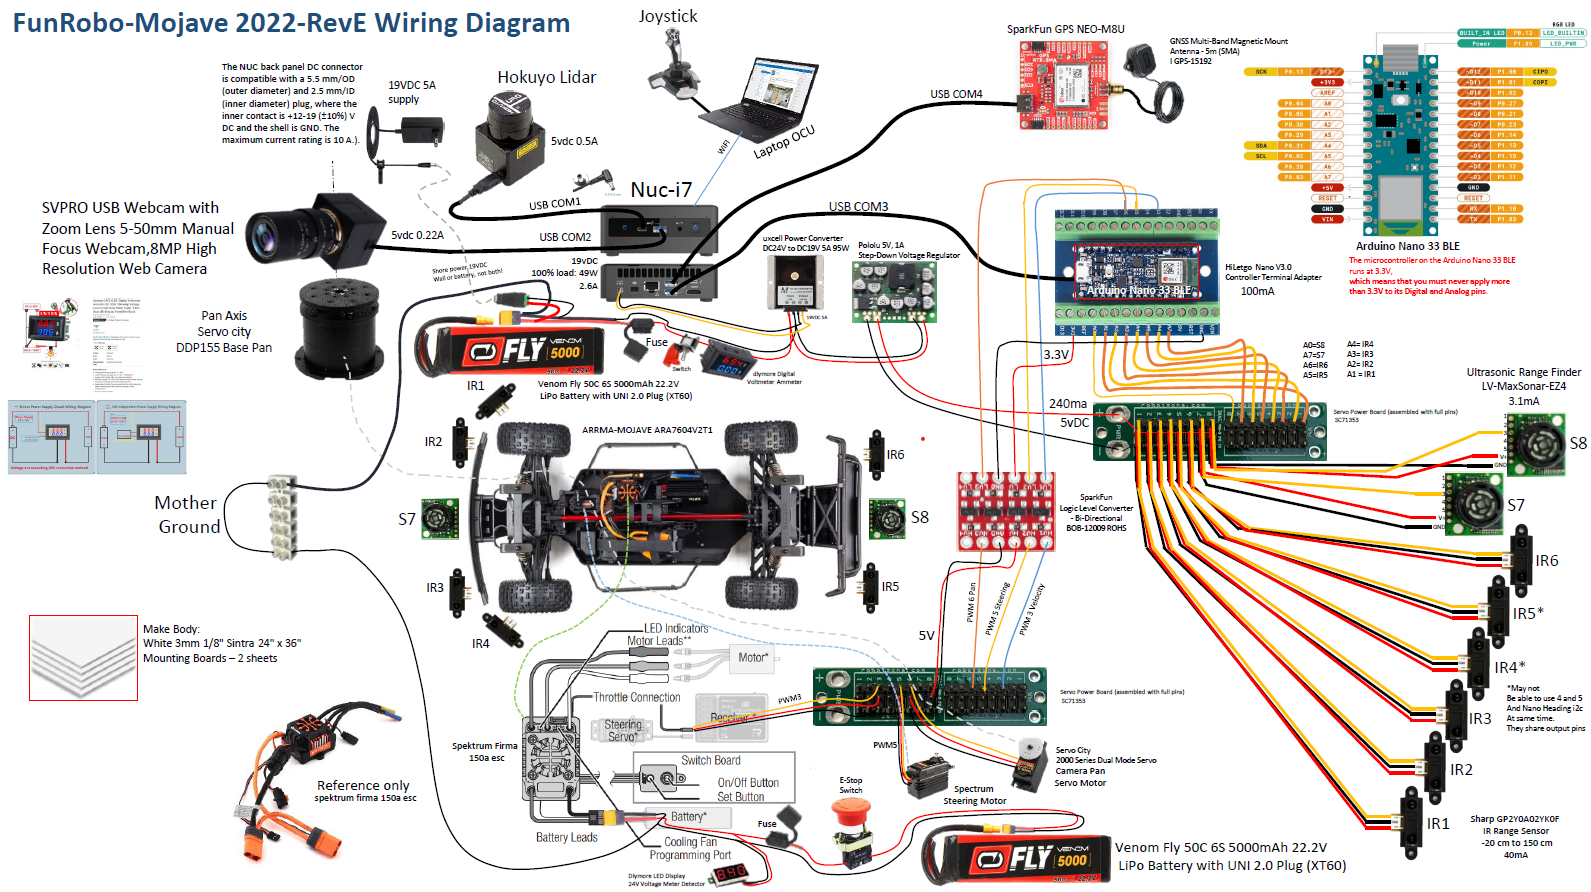

This test code is a scafolding for your Rover control code. This Script will first set up each of the hardware subsystems and create the OCU displays to observe them (code that runs once) and then will move into a continuous loop so that you can experimentally collect data from them for your Rover code (code that runs in control loop). It will aslo let you collect your Rover's current GPS position as well as observe the raw input analog signal voltage from your Rover's Sharp IR Range and Maxbotic Sonar sensors. You will still need to add calibration code to each of those to turn those voltages into useful range measurements. Please note, your teams goal is to develop functions independantly on your laptops and then share them(via MatlabDrive) with one common set of flight code on your Rovers NUC that you access via Windows 10 remote desktop.

**Note! Never hook up your Hardware Hot, Never ever let 22V battery voltage touch any Nano 33BLE pins!!!!  Please don't burn out your Nano!!!**

*At end of each programming session, please don't forget to shutdown your Nano cleanly by using shutdown code provided at the end of this file. If you down sut it all down cleanly, each time, you can jam it so badly, it won't restart. *

clc                     % clear command window
clear                   % clear MATLAB workspace
clf                     % clear figures
% profile on            % profile used to time each segment of code

**#########################################################################**

**Set up robot control system** ( code that runs once )

% create arduino nano 33 BLE and arduino-velocity servo ref-objects
% Note: your COMPORT number might be different !  Use Windows utilities to
% find correct number

  [robotArduino]= SETUPARDUINO('COM5')              % semi-colon left off to confirm Nano is connected

robotArduino =   arduino with properties:

                  Port: 'COM5'
                 Board: 'Nano33BLE'
         AvailablePins: {'D0-D13', 'A0-A7'}
  AvailableDigitalPins: {'D0-D13', 'A0-A7'}
      AvailablePWMPins: {'D0-D13'}
   AvailableAnalogPins: {'A0-A3', 'A6-A7'}
    AvailableI2CBusIDs: [0, 1]
AvailableSerialPortIDs: [1]
             Libraries: {'I2C', 'Servo'}
Show all properties


First, set up your Rover's Servos so that they are in a safe, stable initial operation point

% create and stabilize test setup servo actutaors
% create three servo objects driving PWM pin 3, pin 5 and pin 6
% MinPulseDuration: 1120 (microseconds)  center 1520 (microseconds)
% MaxPulseDuration: 1920 (microseconds)
  steerServo = servo(robotArduino, 'D5', 'MinPulseDuration', 10*10^-6, ...
      'MaxPulseDuration', 1925*10^-6);
  driveServo = servo(robotArduino, 'D3', 'MinPulseDuration', 10*10^-6, ...
      'MaxPulseDuration', 1925*10^-6);
  panServo = servo(robotArduino, 'D6', 'MinPulseDuration', 10*10^-6, ...
      'MaxPulseDuration', 1925*10^-6);

% Servos in R-C Mode expect to start up with joystick centered
% In MATLAB function servo position is 0-1 so 0.5 (1520ms) is centered
  writePosition(steerServo, 0.5);      % always start servo-command at 0.5
  writePosition(driveServo, 0.5);      % always start servo-command at 0.5
  writePosition(panServo, 0.5);        % always start servo-command at 0.5
  pause(3.0);                          % wait for Arduino to send stable pwm
  warning ('actuators live');

Next set up your Nano's internal IMU and magnetometer. IMU can be used to prevent flips and tips.

Angular velocity can give good yaw rate control.

Magnetometer can give you a accurate stationary heading wrt magnetic North.

% create interal Nano sensor inputs, connect to sensor over I2C bus
lsmObj = lsm9ds1(robotArduino,"Bus", 1);           % create internal LSM9DS! sensor object
[roverAcceleration,timeStampA] = readAcceleration(lsmObj)           % fishAccl x,y,z,t m/s2

roverAcceleration =    -0.0653    0.1162    9.6477


timeStampA = datetime
   7-Apr-2022 20:44:04.899


[roverAngularVelocity, timeStampV] = readAngularVelocity(lsmObj)    % angVel x,y,z, t rad/s

roverAngularVelocity =     0.0087   -0.0191   -0.0127


timeStampV = datetime
   7-Apr-2022 20:44:04.974



[roverMagneticField, timeStampM] = readMagneticField(lsmObj)        % magfiled x,y,z,t microTesla

roverMagneticField =    45.9340    8.1060  -41.4680


timeStampM = datetime
   7-Apr-2022 20:44:05.058


Set up your analog input ports for Sharp IR range and Maxbotix Sonar Sensors  

(two done here, you can add the rest)

% create force sensor analog inputs for lift and drag on test fin
configurePin(robotArduino,"A1","AnalogInput");
configurePin(robotArduino,"A2","AnalogInput");

ir1 = 'A1';
ir1tVoltage = readVoltage(robotArduino, ir1);
formatSpec = 'ir1Voltage is %4.3f v \n';
fprintf(formatSpec,ir1tVoltage);

ir1Voltage is 2.004 v 



ir2 = 'A2';
ir2Voltage = readVoltage(robotArduino, ir2);
formatSpec = 'ir2Voltage is %4.3f v \n';
fprintf(formatSpec,ir2Voltage);

ir2Voltage is 1.524 v 


Create a couple of fixed OCU windows for plotting rover data

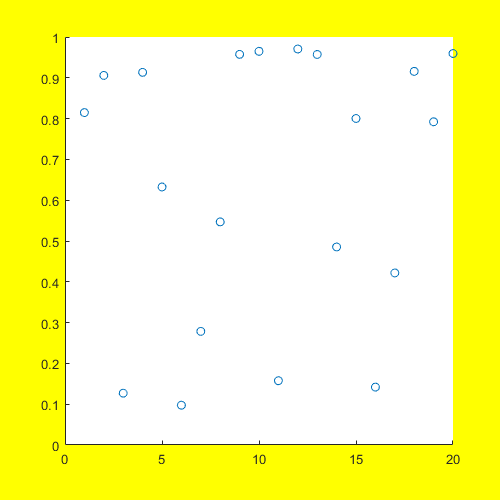

% create an OCU window

f1=figure('Name','Rover Location','NumberTitle','off','Color','yellow' );
f1.Position = [80 100 500 500];         % sets window location and size
scatter((1:20),rand(1,20));             % loads in a random plot
set(gcf,'Visible','on')

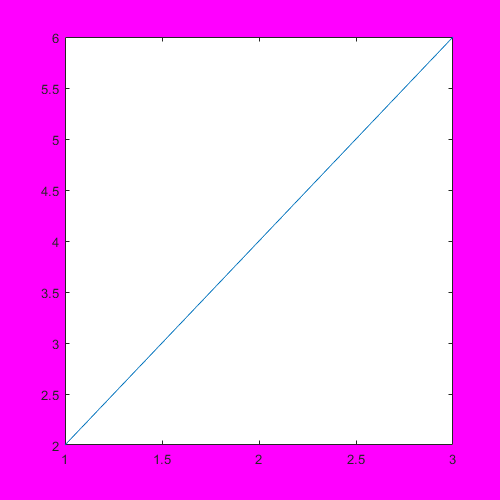


f2 = figure('Name','Rover Sensors','NumberTitle','off','Color','magenta');
f2.Position = [800 100 500 500];        % sets window location and size
plot([1 2 3],[2 4 6]);                  % load another random plot
set(gcf,'Visible','on')

This code sets up Joystick  (note: you may need to go to add-ins and add Simulink VR sim toolbox to use Joystick functions)

% Define joystick ID (if only using 1 joystick, this will likely be '1')
ID = 1

ID = 1

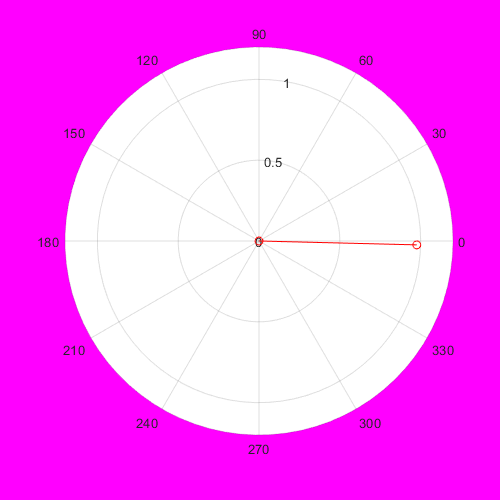

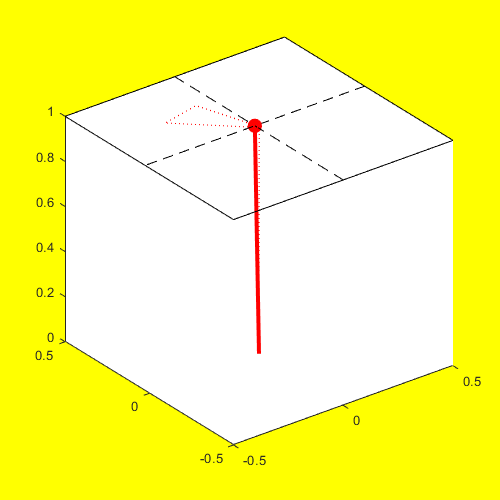

% Create joystick variable, need VR toolbox loaded to access this function
joy=vrjoystick(ID);                                

%-------------------------------------------------------------------
% Next code makes pretty graphs of joystick X, Y, twist and thrust
% in the figures you just created. You probably don't need this level
% Joystick tracking for your rover. Its just here to demostrate how to
% dynamically draw data in figure and because it looks cool.
% for rover just need forward-reverse, turn and pan.

% Select the number of graphictime steps to rememeber 
% (i.e., trailing tail length)
n=100;

% Preallocate joystick graphic vectors
kz=zeros(1,n);
ky=zeros(1,n);
kx=zeros(1,n);

% Preallocate rotary vectors
theta = [ 0 0 ];
rho  = [ 0 0 ];

% loop test Joystick until trigger is pressed
% probably should remove this loop from flight code after testing
% out Joystick and figure drwing code
while true
    Y=axis(joy, 1);     % X-axis is joystick axis 1
    X=axis(joy, 2);     % Y-axis is joystick axis 2
    y=-sin(Y*pi/6);      % Correlate axis to angular orientation of joystick
    x=-sin(X*pi/6);      % See above.
    z=sqrt(1-x^2-y^2);  % Vertical height of joystick by Pythagoras
    
    % Define vector representing current joystick orientation
    z_v = [0 1]*z;
    y_v = [0 1]*y;
    x_v = [0 1]*x;
    
    % Define vectors representing joystick orientation history 
    kz(end+1)=z;
    kz=kz(2:n+1);
    ky(end+1)=y;
    ky=ky(2:n+1);
    kx(end+1)=x;
    kx=kx(2:n+1);   

    % Plot marker to define end of joystick
    figure(f1)
    plot3(x,y,z,'ro','MarkerSize',10,'MarkerFaceColor','r');
    hold on
    
    % Plot current orientation of joystick
    plot3(x_v,y_v,z_v,'-r','LineWidth',3);
    hold on
    
    % Plot Y-reference vector (it can be hard to tell where things are
    % in 3D plots)
    plot3([.5 -.5],[y y],[z z],'--k');
    hold on
    
    % Plot X-reference vector
    plot3([x x],[.5 -.5],[z z],'--k');
    hold on
    
    % Plot historical data (if n>0)
    plot3(kx,ky,kz,':r');
    hold on
    
    % Plot box around plot perimeter for altitude reference
    plot3([-.5 .5 .5 -.5 -.5],[-.5 -.5 .5 .5 -.5],[z z z z z],'-k');
    hold off
    
    % define plot axes
    axis([-.5 .5 -.5 .5 0 1]);
    
    % force the plot
    drawnow;
    
    % delay between plots
    pause(.05)

    [a,b,p] = read(joy);     % read joystick
    if (b(1) == 1)           % if trigger button is pressed
        break;               % exit loop
    end
    
    % Plot marker to rotation and thrust of joystick
    % in second Figure
    figure(f2)   
    theta(2) = a(3)*pi;
    rho(2) = a(4);
    polarplot(theta,rho,'r-o')
    rlim([0 1.2]);
    % force the plot
    drawnow;
end

% recomend remove the above loop for rover flight code
% take what you need from it and build your Joystick control
% --------------------------------------------------------------


This code creates an example of a floating user input box

prompt = {'Enter waypoint matrix size:','Enter data log name:'};
dlgtitle = 'Input';
dims = [1 35];
definput = {'Enter Size Here','Enter Name Here'};
answer = inputdlg(prompt,dlgtitle,dims,definput);
user_val = str2double(answer{1});

% rewrite code to enter useful rover test parameter for your rover

This code creates an  example of an on screen E - stop button

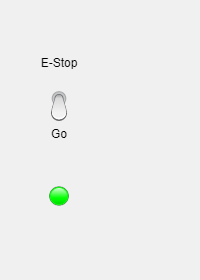

ESTOPswitch;

Create GPS object and collect first Rover GPS location

see [https://learn.sparkfun.com/tutorials/sparkfun-gps-dead-reckoning-neo-m8u-hookup-guide](https://learn.sparkfun.com/tutorials/sparkfun-gps-dead-reckoning-neo-m8u-hookup-guide) for hookup and technical details

Please see [https://learn.sparkfun.com/tutorials/three-quick-tips-about-using-ufl](https://learn.sparkfun.com/tutorials/three-quick-tips-about-using-ufl) for how to connect your ufl antenna and be 

extraodinarily careful when making the actual connection. Break this connector and GPS is toast and your team doesn't have a spare.

**Note: You will need to connect your GPS over USB to your laptop and run U-Center to configure your GPS before using.** See Canvas GPS tutorial  for detailed walkthrough of how to configure your GPS

First time you hook up GPS, do the follwing:

1.Download the Ublox GPS application:

[https://www.u-blox.com/en/product/u-center](https://www.u-blox.com/en/product/u-center)   

2. Follow the detailed Ublox GPS configuration instructions in canvas.

Note:  The time to first fix will about **~26 seconds**, but after it has a lock, that battery will allow for about a **1.5 second** time to first fix. 

This is known as a **hot start** and lasts for four hours after the board is powered down. The battery provides over a years worth of 

power to the backup system and charges slowly when the board is powered. To charge it to full, leave your module plugged in for 48 hours.

**Note: GPS data will jump around once per second, in a 10 m circle, see below:**

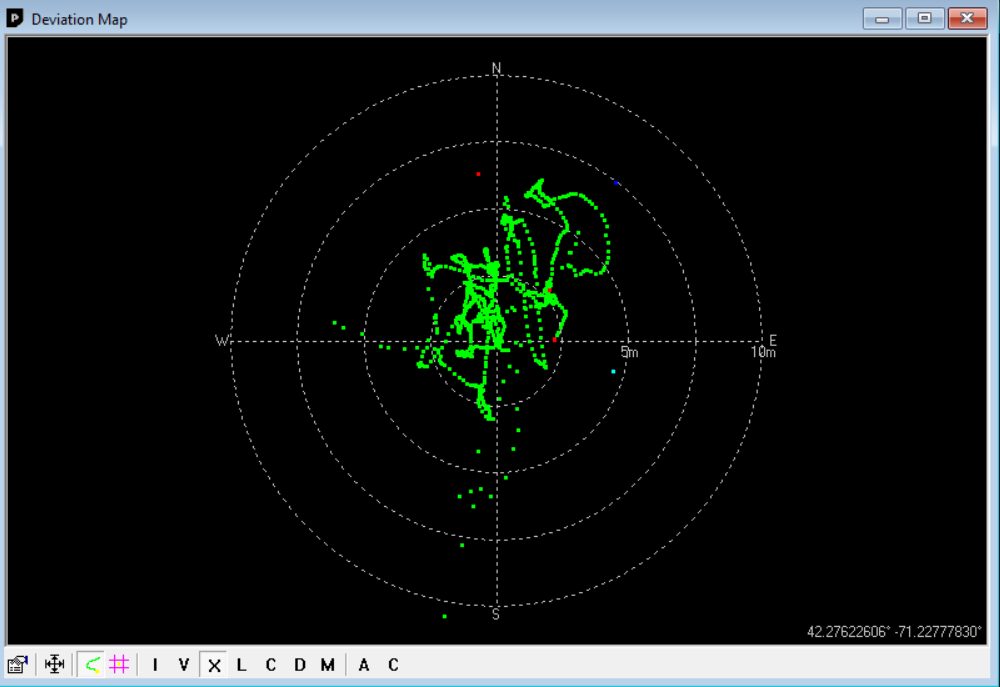

## Get the coordinates of a place

- On your computer, open [Google Maps](https://www.google.com/maps). Zoom to Olin Campus. 

- Right-click the place or area on the map, you want Longitude and Latitude of.

- Select the latitude and longitude, this will automatically copy the coordinates.

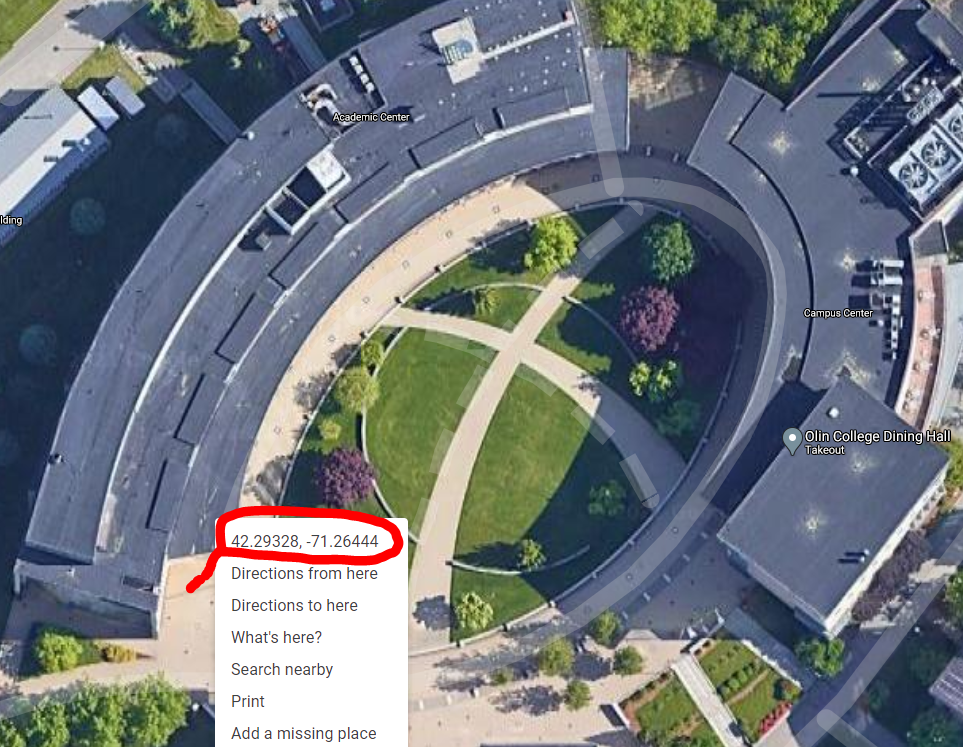

Click on a few waypoints and write down their coordinates for latter use.

Set up Ublox-Neo GPS : Please note, YOU MUST USE YOUR ROBOTS COM# in code below 


neo = NEO_M8U_USB("COM7");         % Create a GPS Class Instance, replace COM7 with your COM#

obj =   NEO_M8U_USB with properties:

         DEFAULT_NAME: "USB_NEO_M8U"
    DEFAULT_BAUD_RATE: 9600
    DEFAULT_DATA_TYPE: "uint8"
                  ubx: [1×1 UBX]
               device: [1×1 internal.Serialport]
                 data: []


pause(2);                          % Let GPS get up to speed

% the function neo.getBasic()
% returns a struct with fields: longitude, lattitude, roll, pitch, and heading.
       
basic_data = neo.getBasic()

basic_data = struct with fields:
    longitude: -71.2278
    lattitude: 42.2763
         roll: 0
        pitch: -76.9678
      heading: 324.5170



roverX = basic_data.longitude

roverX = -71.2278

roverY = basic_data.lattitude

roverY = 42.2763

roverHeading = basic_data.heading

roverHeading = 324.5170

% Create a stand alone figure to plot GPS rover position data in
gpsRoverPlot=figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
% Plot out a trail line bewteen two waypoints just to demo line drawing
geoplot([42.293 42.294],[-71.265 -71.262],'y-')
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
geoplot(42.2935, -71.264, 'r*')
% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Rover GPS Track')
movegui(gpsRoverPlot,'south');

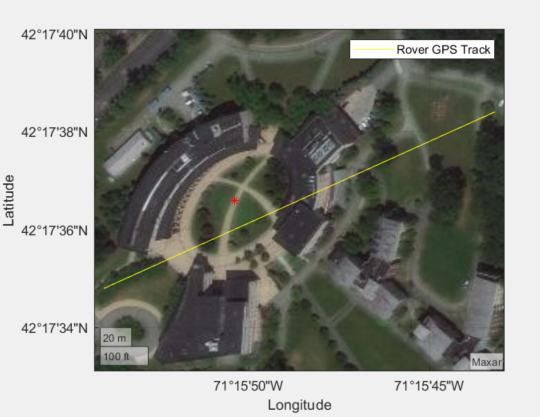

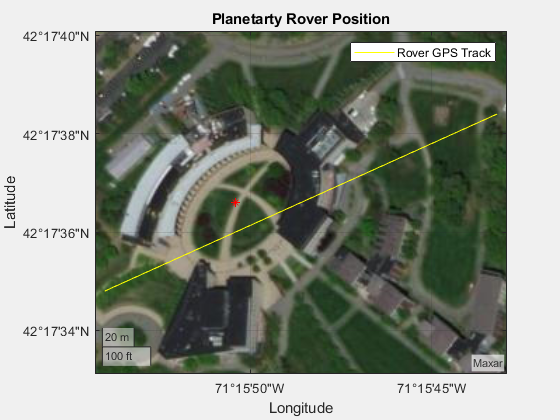

title('Planetarty Rover Position')

Create a Mission Definition File (MDF) of Rover waypoints in a Matlab Table:

% create index for MDF table
WayPoint = (1:1:10);                                        
WayPoint = WayPoint';

% create inital target waypoints
xLongitude = [ -71.227875 ; -71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875];
yLatitude = [ 42.276295 ; 42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ];

% build vector list of desired behaviors
Behavior = ['Pause___' ; 'GoToWPT_'; 'Pause___' ;'FindDock' ;'GoToWPT_' ;'Pause___' ;'FindDock' ;'GoToDock' ;'null____' ;'null____'  ];

% build Mission Definition File (MDF) table
MDF = table(WayPoint,xLongitude,yLatitude,Behavior)

MDF = 10×4 table
    WayPoint    xLongitude    yLatitude    Behavior
    ________    __________    _________    ________

        1        -71.228       42.276      Pause___
        2        -71.228       42.276      GoToWPT_
        3        -71.228       42.276      Pause___
        4        -71.228       42.276      FindDock
        5        -71.228       42.276      GoToWPT_
        6        -71.228       42.276      Pause___
        7        -71.228       42.276      FindDock
        8        -71.228       42.276      GoToDock
        9        -71.228       42.276      null____
       10        -71.228       42.276      null____


Note: use curly braces { } to extract data from a table, in this case MDF

WPn = 1;
wayPointX = MDF{WPn,2}

wayPointX = -71.2279

wayPointY = MDF{WPn,3}

wayPointY = 42.2763

roverBehavior = MDF{WPn,4} 

roverBehavior = 'Pause___'

Create global variables for main control loop  and an index for tracking loop iterations.

sampleTime = 0.5;                                  % Sample time [s]
t = 0:sampleTime:100;                              % Time array
r = rateControl(1/sampleTime);                     % set control loop  rate
reset(r);                                          % reset loop time to zero

Ready to run robot, ask operator if they are set and suggest they move plots to a visable position

userInput = questdlg('Ready to run Rover?', 'Start Mission');
warning('Warning! Rover Active! ');   

**##################################################################################**

**Run robot control loop **( code that runs over and over )

if (strcmp(userInput,'Yes'))
    comSteer = 50;                       % set steering center
    comSpeed = 50;                       % set drivespeed to zero
    controlFlag = 1;                     % create a loop control
while (controlFlag < numel(t))           % loop for number of elements in t
    
    %controlTime = r.TotalElapsedTime;    % running register of control loop time
    
    % SENSE ------------------------------
    % take joystick steer and speed commands from operator
    [comSteer, comSpeed] = SENSE_JoyStick(joy);
        % add your camera, SharpIR, GPS, IMU and Sonar functions here
        % recomend you do bulk of signal processing in functions
        % recomend every team member write one sense function 
    
    %THINK------------------------------------------------------------
    % add code here that checks rovers current state with goal in MDF
    % and updates target waypoint appropriately
    % recomend that bulk of think code is functions
    % recomend that each teammember write at least one think function
    WPn = 1;                                  % replace this with updating waypoint code
    wayPointX = MDF{WPn,2};
    wayPointY = MDF{WPn,3};
    roverBehavior = MDF{WPn,4}; 
    % compute what robot should do next
    
    % ACT-------------------------------------------------------------
    % add code here tocommand all servo motors to desired velocity 
    % recomend that bulk of code be function based and all team members
    % get to write an ACT function
    
    % stop loop by pressing joystick button 1
    b = button(joy, 1);
    if (b == true)
        break;
    end
    
    waitfor(r);                          % wait for loop cycle to complete  
    controlFlag = controlFlag+1;         % increment loop
    
end 
end  % if (strcmp(userInput,'Yes'))


### #####################################################################

### Mission data processing

For many robot applications, you will need to post-process the data collected after

the mission. 

  % Plot and store mission data vs. time, maybe your gps rover track?
  % write experimental data to a file for later use
  % example:
  % save steerServoData.dat steerServoData -ascii  
  % save driveServoData.dat driveServoData -ascii  

### Clean shut down

finally, with most embeded robot controllers, its good practice to put 

all actualtors into a safe position and then release all control objects and shut down all

communication paths. This keeps systems from jamming when you want to run again.

% Stop program and clean up the connection to Arduino
% when no longer needed 
  writePosition(steerServo, 0.5);      % always start servo-command at 0.5
  writePosition(driveServo, 0.5);      % always start servo-command at 0.5
  writePosition(panServo, 0.5);        % always start servo-command at 0.5
  pause(3.0);                          % wait for Arduino to send stable pwm
  clear steerServo;                    % turn off pwm to steer servo
  clear driveServo;                    % turn off pwm to drive servo
  close(joy);                          % close joystick obect 
  clear lsmObj robotArduino  ;         % clear associated internal sensor object
  clear robotArduino;                  % clear Arduino object
  clc;                                 % clear Command Window
  beep              % play sytem sound to let user know program is ended
  
f = msgbox("Mission Complete, Robot has been successfully shut down");
  

Check quasi real-time loop performance (Dave and Matlab working on ways to speed this up)

  % disp(r);
  % stats = statistics(r)              % check real-time loop execution time stats
  
  % leave next line commented out
  %  profile viewer                    % view code runtimes graphically

**Robot Functions **(store this codes local functions here) ************************************************

In practice for modularity, readability and longitevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions

For this Rover test LiveScript, many of the critical functions are embedded in class definitions in external files.

function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end

function ESTOPswitch
% lampswitch creates a free floating figure with an on-of switch
% and an indicator light
 fig = uifigure('Name','control','Position',[590 100 200 280]);
 lmp = uilamp(fig,...
    'Position',[50 75 20 20],...
    'Color','green');
 sw = uiswitch(fig,'toggle',...
    'Items',{'Go','E-Stop'},...    
    'Position',[50 160 20 45],...
    'ValueChangedFcn',@switchMoved); 
    % ValueChangedFcn callback
    function switchMoved(src,event)  
     switch src.Value
        case 'Go'
            lmp.Color = 'green';
        case 'Stop'
            lmp.Color = 'red';
     end
    end
 end

**Sense Functions** (store all Sense related local functions here)

function [comSteer, comSpeed] = SENSE_JoyStick(Joy)
% this function polls USB joystick and returns x position 
% for Rover steering angle and y position for Rover velocity
    stickX = axis(Joy, 1);     % X-axis is joystick axis 1 (-1 to 1)
    stickY = axis(Joy, 2);     % Y-axis is joystick axis 2 (-1 to 1)
    comSteer = 0 + (1 * stickX);  % scale X for servo with pulse centered at 50
    comSpeed = 0 + (-1 * stickY);  % scale Y for servo with pulse centered at 50
end

% SENSE: Red Circe Dock Detection
function [roverOccupancyGrid, circleBearing, circleRange] = redCircleFind(roverOccupancyGrid)
    % redCircle scans pan space for red circle. FInd circle and adds the current circle
    % location to  Rover centric occupancy grid. 0=open space 1-10= obstacles
    % 20 = dock
end

% SENSE: April Tag Range and Detection
function [roverOccupancyGrid, tagBearing, tagRange] = findApriltag(roverOccupancyGrid)
    % findAprilTag scans the space around the rover and adds any April Tag found to
    %the rover  centric occupancy grid. 0=open space 1-10= obstacles
    % 20 = dock, 40 = April Tag
end

% SENSE: Hokuyo Lidar Obstacle Detection
function [roverOcupancyGrid] = scanLaser(roverOcupancyGrid)
    % scanLaser adds PiCam lidar range data to
    % loop cycle’s Rover centric occupancy grid. 0=open space 1-10= obstacles
    % 1-3 drive over, 4-10 drive around
    % 20 = dock

end

**Think Functions** (store all Think related local functions here)

(some possible example functions given below)

function [ steerSetPoint, driveSetPoint] = THINK(WPn, wayPointx,wayPointY, roverBehavior)
   % add thinking code here
   % Behavior = ['Pause___' ; 'GoToWPT_'; 'Pause___' ;'FindDock' ;'GoToWPT_' ;'Pause___' ;'FindDock' ;'GoToDock' ;'null____' ;'null____'  ];
   WPn = WPn +0;                                              % next 5 lines are placeholders to remove complier warnings
   wayPointx = wayPointx +0 ;                                 % please replace with actual code
   wayPointY = wayPointY +0;
   notused = WPn + wayPointx + wayPointY; 
   notused = notused+0;
  
   switch roverBehavior
       case 'Pause___'
           % stop and look around?
           [ steerSetPoint, driveSetPoint] = THINK_Pause();
       case 'GoToWPT_'
           % do pure pursuit to next waypoint
           [ steerSetPoint, driveSetPoint] = THINK_GoToWPT();
       case 'FindDock'
           % look for dock?
           [ steerSetPoint, driveSetPoint] = THINK_FindDock();
       case 'GoToDock'
           % drive to dock?
           [ steerSetPoint, driveSetPoint] = THINK_GoToDock();    
       otherwise 
           % do pause behavior
           [ steerSetPoint, driveSetPoint] = THINK_Pause();
   end
   [ steerSetPointOA, driveSetPointOA] = THINK_ObAvoid();
   [ steerSetPoint, driveSetPoint] = THINK_Arbiter(steerSetPointOA, driveSetPointOA, steerSetPoint, driveSetPoint) ;
end

function [ steerSetPoint, driveSetPoint] = THINK_ObAvoid()
   % add obstacle avoid behavior here 
   steerSetPoint = 50;
   driveSetPoint = 50;
end

function [ steerSetPoint, driveSetPoint] = THINK_Pause()
   % add pause behavior here  
   steerSetPoint = 50;
   driveSetPoint = 50;
end

function [ steerSetPoint, driveSetPoint] = THINK_GoToWPT()
   % add go to waypoint behavior here 
   steerSetPoint = 50;
   driveSetPoint = 50;
end

function [ steerSetPoint, driveSetPoint] = THINK_FindDock()
   % add find dock behavior here 
   steerSetPoint = 50;
   driveSetPoint = 50;
end

function [ steerSetPoint, driveSetPoint] = THINK_GoToDock()
   % add go to dock behavior here  
   steerSetPoint = 50;
   driveSetPoint = 50;
end

function [steerSetPoint, driveSetPoint] = THINK_Arbiter(steerSetPoint1, driveSetPoint1, steerSetPoint2, driveSetPoint2)
   % add arbiter here  
   steerSetPoint = (steerSetPoint1 + steerSetPoint2)/2;
   driveSetPoint = (driveSetPoint1 + driveSetPoint2)/2;
end

**Act Functions** (store all Act related local functions here)

function ActDrive(comSteer, comSpeed) 
% is an example of a function to control the two Rover RC servomotors     
   
    
end